# HW2

## Ex.1

syms y yd
ydd = -0.1*yd + y - y^3;

x = [y yd].';
xd = [yd ydd].';
xe1 = [0,0].';
xe2 = [-1,0].';
xe3 = [1,0].';

A = jacobian(xd,x)

$$A = \left(\begin{array}{cc} 0 & 1\\ 1-3\,y^{2} & -\frac{1}{10} \end{array}\right)$$

A1 = subs(A,x,xe1)

$$A1 = \left(\begin{array}{cc} 0 & 1\\ 1 & -\frac{1}{10} \end{array}\right)$$

A2 = subs(A,x,xe2)

$$A2 = \left(\begin{array}{cc} 0 & 1\\ -2 & -\frac{1}{10} \end{array}\right)$$

A3 = subs(A,x,xe3)

$$A3 = \left(\begin{array}{cc} 0 & 1\\ -2 & -\frac{1}{10} \end{array}\right)$$


double(eig(A1))

ans =    -1.0512
    0.9512


double(eig(A2))

ans =   -0.0500 - 1.4133i
  -0.0500 + 1.4133i


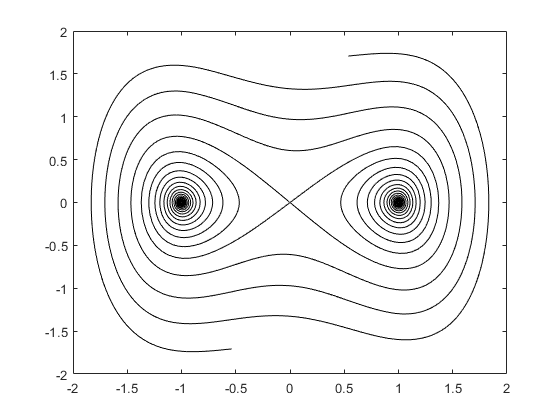

f = @(t,y) [y(2); -0.1*y(2) + y(1) - y(1)^3];

t_vec = linspace(0,100,1e3);
tr_vec = linspace(0,-20,1e3);
[~,y1] = ode45(f,t_vec,[0.001;0]);
[~,y2] = ode45(f,t_vec,[-0.001;0]);
[~,y3] = ode45(f,tr_vec,[0.001;0]);
[~,y4] = ode45(f,tr_vec,[-0.001;0]);
figure
plot(y1(:,1),y1(:,2),'k')
hold on;
plot(y2(:,1),y2(:,2),'k')
plot(y3(:,1),y3(:,2),'k')
plot(y4(:,1),y4(:,2),'k')

## Ex.2

syms y yd
ydd = -sin(y);

x = [y yd].';
xd = [yd ydd].';
xe1 = [0,0].';
xe2 = [pi,0].';

A = jacobian(xd,x)

$$A = \left(\begin{array}{cc} 0 & 1\\ -\cos\left(y\right) & 0 \end{array}\right)$$

A1 = subs(A,x,xe1)

$$A1 = \left(\begin{array}{cc} 0 & 1\\ -1 & 0 \end{array}\right)$$

A2 = subs(A,x,xe2)

$$A2 = \left(\begin{array}{cc} 0 & 1\\ 1 & 0 \end{array}\right)$$


double(eig(A1))

ans =    0.0000 - 1.0000i
   0.0000 + 1.0000i


double(eig(A2))

ans =     -1
     1


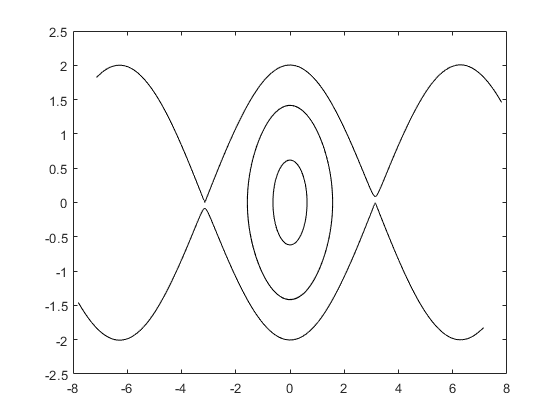

f = @(t,y) [y(2); -sin(y(1))];

t_vec = linspace(0,6*pi,1e3);
tr_vec = linspace(0,-3*pi,1e3);

[~,y1] = ode45(f,t_vec,[0.2*pi;0]);
[~,y2] = ode45(f,t_vec,[0.5*pi;0]);
[~,y3] = ode45(f,t_vec,[-pi;0.001]);
[~,y4] = ode45(f,tr_vec,[-pi;0.001]);
[~,y5] = ode45(f,t_vec,[pi;-0.001]);
[~,y6] = ode45(f,tr_vec,[pi;-0.001]);

figure
plot(y1(:,1),y1(:,2),'k')
hold on;
plot(y2(:,1),y2(:,2),'k')
plot(y3(:,1),y3(:,2),'k')
plot(y4(:,1),y4(:,2),'k')
plot(y5(:,1),y5(:,2),'k')
plot(y6(:,1),y6(:,2),'k')

## Ex.4

f = @(t,x) x^3;

x0 = 1;
tb = 1/(2*x0^2)

tb = 0.5000

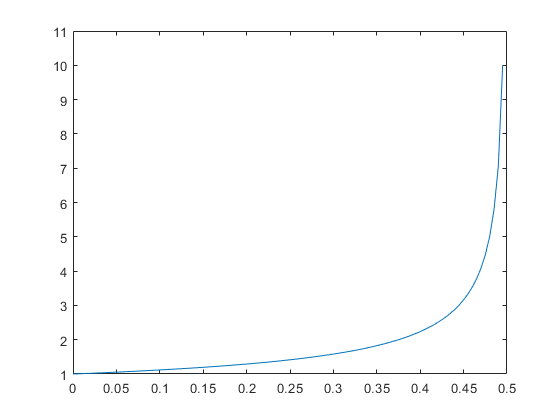

t_vec = linspace(0,tb*0.99);
[t,x] = ode45(f, t_vec, x0);
figure
plot(t,x)